1.4

x = linspace(0, 2, 200);  % Discretize the spatial domain from 0 to 2 with 200 points
t = linspace(0, 10, 201); % Discretize the time domain from 0 to 10 with 201 points

sol = pdepe(0, @Equation, @Init, @BC, x, t);  % Solve the PDE using pdepe

1.5

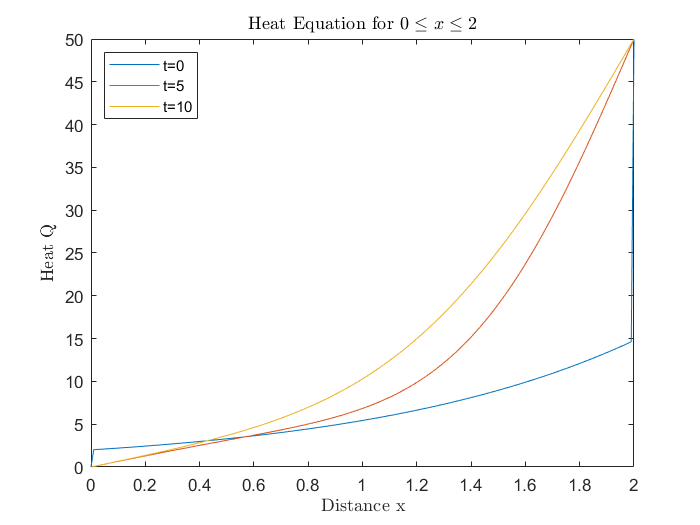

% Plot the solution at different times
plot(x, sol(1,:))       % Plot for t = 0
hold on
plot(x, sol(101,:))     % Plot for t = 5
plot(x, sol(201,:))     % Plot for t = 10
hold off
legend('t=0', 't=5', 't=10', 'Location', 'northwest')  % Add legend
title('Heat Equation for $0 \le x \le 2$', 'interpreter', 'latex')  % Title of the plot
xlabel('Distance x', 'interpreter', 'latex')  % X-axis label
ylabel('Heat Q', 'interpreter', 'latex')      % Y-axis label

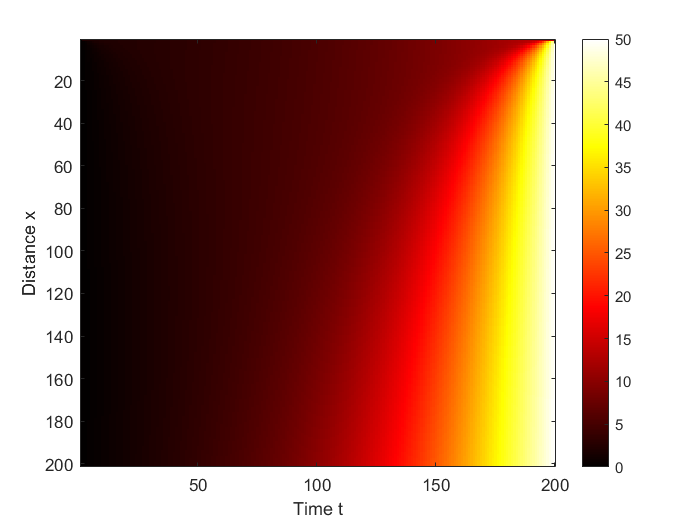

imagesc(sol)  % Display the solution as an image
colormap hot  % Apply hot colormap
xlabel('Time t')  % X-axis label
ylabel('Distance x')  % Y-axis label
colorbar  % Add colorbar

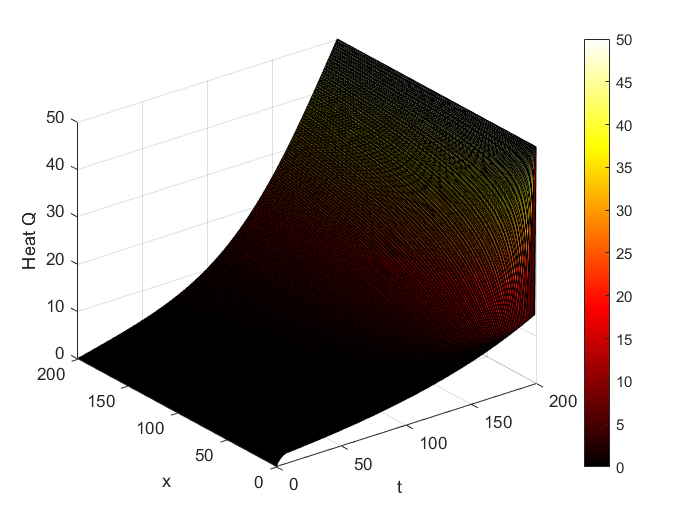

surf(sol)  % Display the solution as a 3D surface plot
xlabel("t")  % X-axis label
ylabel("x")  % Y-axis label
zlabel('Heat Q')  % Z-axis label
colorbar  % Add colorbar

% Solve the PDE again with different spatial and time discretization
x = linspace(0, 2, 100);  % Discretize the spatial domain from 0 to 2 with 100 points
t = linspace(0, 10, 101); % Discretize the time domain from 0 to 10 with 101 points

sol = pdepe(0, @Equation, @Init, @BC, x, t);  % Solve the PDE using pdepe

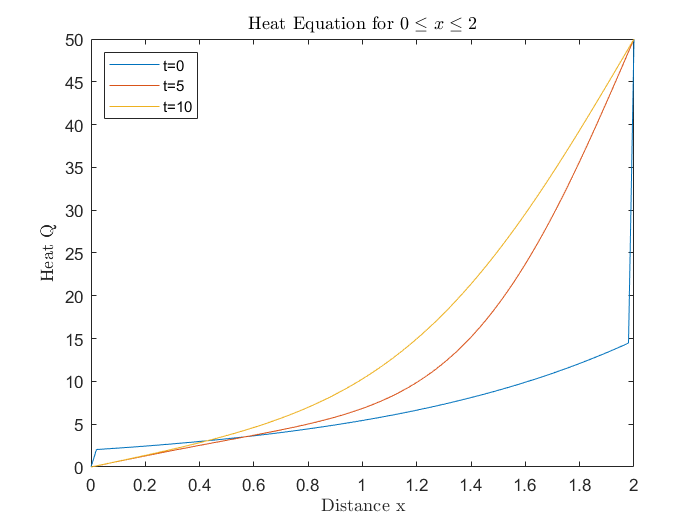

% Plot the solution at different times
plot(x, sol(1,:))       % Plot for t = 0
hold on
plot(x, sol(51,:))      % Plot for t = 5
plot(x, sol(101,:))     % Plot for t = 10
hold off
legend('t=0', 't=5', 't=10', 'Location', 'northwest')  % Add legend
title('Heat Equation for $0 \le x \le 2$', 'interpreter', 'latex')  % Title of the plot
xlabel('Distance x', 'interpreter', 'latex')  % X-axis label
ylabel('Heat Q', 'interpreter', 'latex')      % Y-axis label

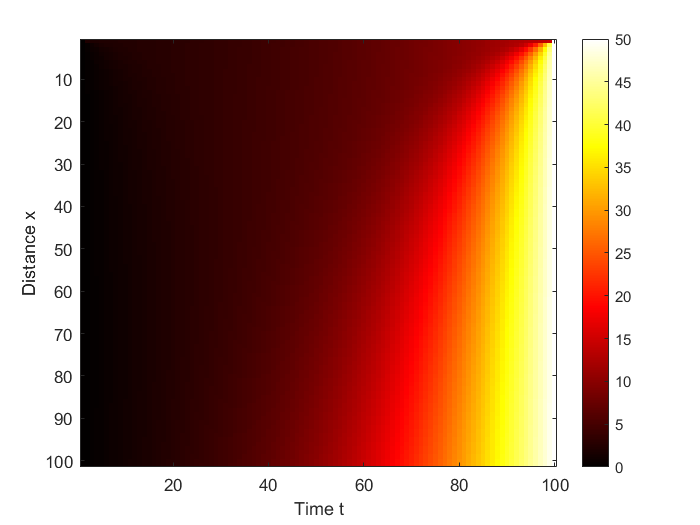

imagesc(sol)  % Display the solution as an image
colormap hot  % Apply hot colormap
xlabel('Time t')  % X-axis label
ylabel('Distance x')  % Y-axis label
colorbar  % Add colorbar

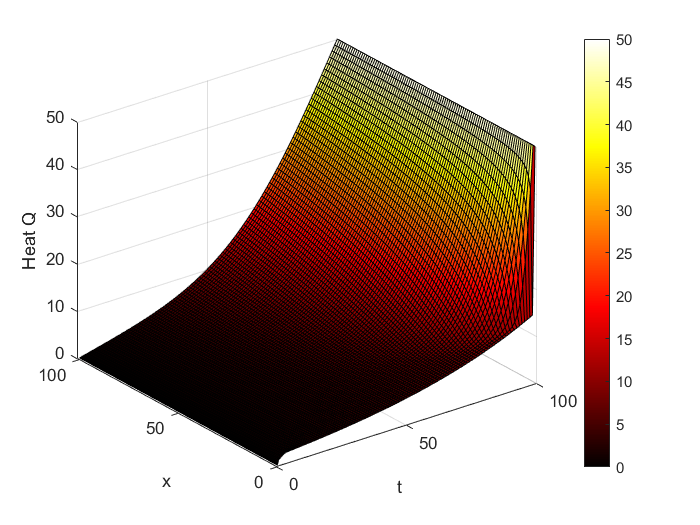

surf(sol)  % Display the solution as a 3D surface plot
xlabel("t")  % X-axis label
ylabel("x")  % Y-axis label
zlabel('Heat Q')  % Z-axis label
colorbar  % Add colorbar

1.1

function [c, f, s] = Equation(x, t, u, DuDx)
    c = 50;    % Coefficient for the time derivative term, scaled by 50
    f = DuDx;  % Flux term representing the spatial derivative of u
    s = 0;     % Source term is zero (no additional source)
end

1.2

function value = Init(x)
    value = 2 .* exp(x);  % Initial condition: u(x, 0) = 2 * exp(x)
end

1.3

function [pl, ql, pr, qr] = BC(xl, ul, xr, ur, t)
    pl = ul;     % Left boundary condition at x = 0
    ql = 0;      % Coefficient for the left boundary
    pr = ur - 50; % Right boundary condition at x = 2
    qr = 0;      % Coefficient for the right boundary
end